# Stock Data - Descriptive Statisics

## 1.

Load data from `stockData_withReturns.mat`. This file contains a table of stock prices, a second table with information about these stocks, and a matrix of the returns calculated from the stock prices.

load stockData_withReturns.mat

## 2.

Create a boxplot of the first 10 mid-cap stock returns. Use the row names of `stockInfo` to label the boxplot. 

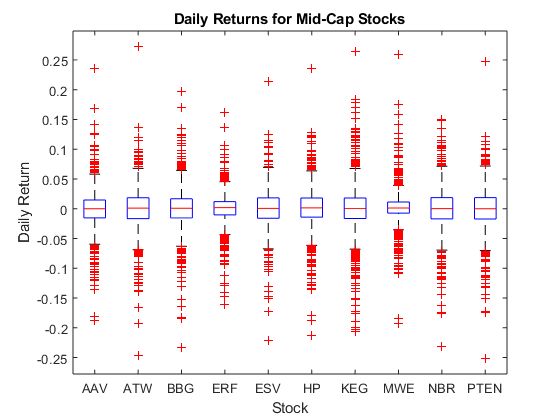

retsMid = rets(:, stockInfo.CapSize == 'Mid');
% Find the first ten midcap stock ticker names:
midCapNames = stockInfo.Properties.RowNames(stockInfo.CapSize == 'Mid');
boxplot(retsMid(:,1:10), 'Labels', midCapNames(1:10))
title('Daily Returns for Mid-Cap Stocks')
xlabel('Stock')
ylabel('Daily Return')

## 3. 

Use `grpstats `to compute the mean and the standard deviation of the stock returns grouped by `CapSize`.

[avRet, stdRet] = grpstats(rets', stockInfo.CapSize, {'mean', 'std'})

avRet =    -0.0069    0.0074   -0.0091   -0.0008    0.0023   -0.0001    0.0054    0.0113   -0.0030    0.0009   -0.0033   -0.0046    0.0024   -0.0074    0.0039    0.0017    0.0063   -0.0055    0.0042    0.0066    0.0070   -0.0065   -0.0011   -0.0117   -0.0166   -0.0119   -0.0022   -0.0153   -0.0144   -0.0070   -0.0097    0.0023   -0.0150    0.0162    0.0029   -0.0101    0.0086    0.0060    0.0077   -0.0224   -0.0048   -0.0106   -0.0049    0.0016   -0.0204   -0.0294    0.0080    0.0352   -0.0006   -0.0190
   -0.0087    0.0030   -0.0152    0.0063    0.0093    0.0063    0.0199    0.0139   -0.0085    0.0002   -0.0089   -0.0077   -0.0115    0.0027    0.0041   -0.0049    0.0026   -0.0018    0.0111    0.0074   -0.0025   -0.0020   -0.0072   -0.0177   -0.0249   -0.0167   -0.0031   -0.0233   -0.0134    0.0009   -0.0113   -0.0021   -0.0013    0.0263    0.0133   -0.0173    0.0253    0.0123    0.0109   -0.0359   -0.0056   -0.0174   -0.0046   -0.0040   -0.0303   -0.0288    0.0150    0.0345   -0.0106 

stdRet =     0.0228    0.0603    0.0209    0.0243    0.0188    0.0182    0.0340    0.0184    0.0245    0.0202    0.0177    0.0289    0.0268    0.0257    0.0189    0.0242    0.0274    0.0173    0.0189    0.0173    0.0227    0.0207    0.0198    0.0201    0.0194    0.0408    0.0248    0.0303    0.0327    0.0432    0.0176    0.0356    0.0255    0.0255    0.0211    0.0298    0.0270    0.0256    0.0321    0.0220    0.0191    0.0275    0.0277    0.0251    0.0324    0.0339    0.0314    0.0305    0.0281    0.0292
    0.0311    0.0196    0.0186    0.0142    0.0138    0.0295    0.0169    0.0315    0.0143    0.0242    0.0161    0.0166    0.0253    0.0269    0.0194    0.0264    0.0200    0.0195    0.0440    0.0244    0.0164    0.0154    0.0417    0.0187    0.0225    0.0217    0.0313    0.0203    0.0195    0.0231    0.0204    0.0169    0.0194    0.0177    0.0181    0.0162    0.0255    0.0166    0.0132    0.0302    0.0189    0.0263    0.0131    0.0176    0.0204    0.0273    0.0272    0.0161    0.0166

## 4. 

The 95% confidence intervals can be found by adding/subtracting a value of 1.96*standard deviation to/from the mean. Find the upper and lower 95% confidence intervals for the small-cap stock returns, and plot these along with the mean small-cap return.

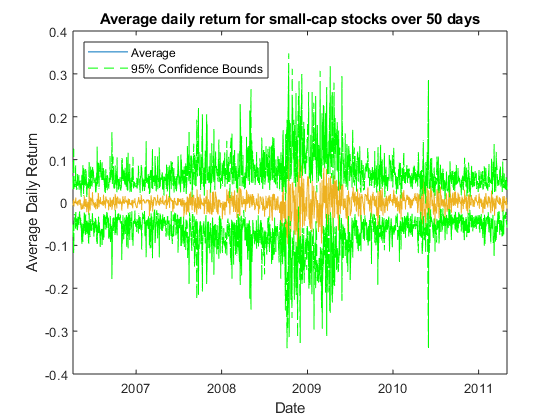

dates = stockPrices.Date(2:end);
upperCI = avRet + 1.96*stdRet(1,:);
lowerCI = avRet - 1.96*stdRet(1,:);

plot(dates, avRet(1, :))
hold on
plot(dates, [upperCI; lowerCI], 'g--')
xlabel('Date')
ylabel('Average Daily Return')
title ('Average daily return for small-cap stocks over 50 days')
legend('Average', '95% Confidence Bounds', 'Location', 'northwest')

## BONUS

Use `grpstats`to compute the skewness and kurtosis of the stock returns grouped by `CapSize`. Plot the skewness and kurtosis for all cap sizes onto two subplots.

[skew, kurt] = grpstats(rets', stockInfo.CapSize, {@skewness, @kurtosis})

skew =     0.8917    6.2385   -0.6719   -0.6184    1.3615   -0.1211   -3.6115    0.1608   -2.2617   -0.1355    0.4936   -2.2094    0.9893    0.8287   -1.5289    0.7504   -1.0478   -0.4880    0.4870    0.2609    1.1872   -1.5643   -0.1111    0.8794   -0.5962   -0.5257   -0.4425   -0.7426    0.2745   -4.0650   -0.3720    2.0069   -1.0921    1.9615   -3.0572    1.1349   -1.9174   -0.2525    3.7128   -0.0618   -0.0706   -0.8545    0.3562    1.3688    3.0058   -1.0192    1.1053    0.2890   -0.4196    0.2367
    3.9757   -0.1968   -1.2725    0.1328    1.5710    2.7981    0.1536    0.3224   -0.8583   -2.3451   -0.6673    2.1065   -1.4583    0.8411   -0.3185   -0.3172    0.4968    0.2868    2.6656   -1.5254    0.4173    0.5930    0.3911   -0.2928    0.2746    0.0229    2.8065    0.7878    0.5909   -1.9538    0.2133    0.3783    0.2290    0.6303    0.8038    0.3844    0.1368    0.7955   -0.6991   -1.5696   -1.2190   -0.1777   -0.1077    1.4564    0.1774   -0.6516    1.0216   -0.6025   -0.9555  

kurt =     5.7964   44.1679    5.1807    6.7051    7.0270    5.6316   22.0148    2.9192   13.9784    4.1028    3.2493   13.4214    5.0258    7.9682    8.7042    6.0219    5.9843    3.0124    3.9492    4.8859    4.1067    6.7338    6.3630    4.8955    3.8745    6.2548    9.4814    6.4214    4.8442   27.0254    3.9832   13.0962    4.8595    8.5542   19.2022    7.5476   13.2891    4.7179   23.4909    3.1201    4.6219    3.8681    7.5777    6.3729   16.5583    4.3584   11.5310    3.3474    6.7027    6.3338
   21.7645    3.3116    7.9384    2.6094    6.8945   16.7524    4.3464   12.1416    4.0200   13.1816    5.6725   11.6276    8.8682    4.1672    5.2977    2.5284    2.1407    3.6535   16.2185    7.2391    4.7498    5.6028   13.0849    2.2430    3.3158    2.9166   19.7652    5.5896    2.8000   11.8674    4.6288    3.4038    2.6922    4.0026    3.0443    3.2297    5.9438    3.7423    2.7164    8.5962    8.3164    2.2136    2.8950    5.8532    2.1956    4.3002    8.3990    4.3010    4.4657  

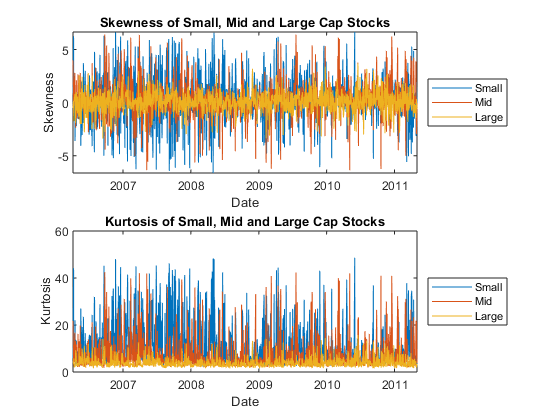


% Plot onto subplots
figure
subplot(2,1,1)
plot(stockPrices.Date(2:end), skew)
title('Skewness of Small, Mid and Large Cap Stocks')
ylabel('Skewness')
xlabel('Date')
legend(categories(stockInfo.CapSize), 'Location', 'eastoutside')

subplot(2,1,2)
plot(stockPrices.Date(2:end), kurt)
title('Kurtosis of Small, Mid and Large Cap Stocks')
ylabel('Kurtosis')
xlabel('Date')
legend(categories(stockInfo.CapSize), 'Location', 'eastoutside')